# Optimal writing paths

This assignment aims at providing optimal paths for a robot arm with a pen on its end effector to write an arbitrary sequence of letters and or/ digits (a word or a sentence). The font Helvetica is chosen for the letters as it is as of 2021 the most used font color worldwide. The following image (click on R`un Section`) summarizes all the letters and digits.

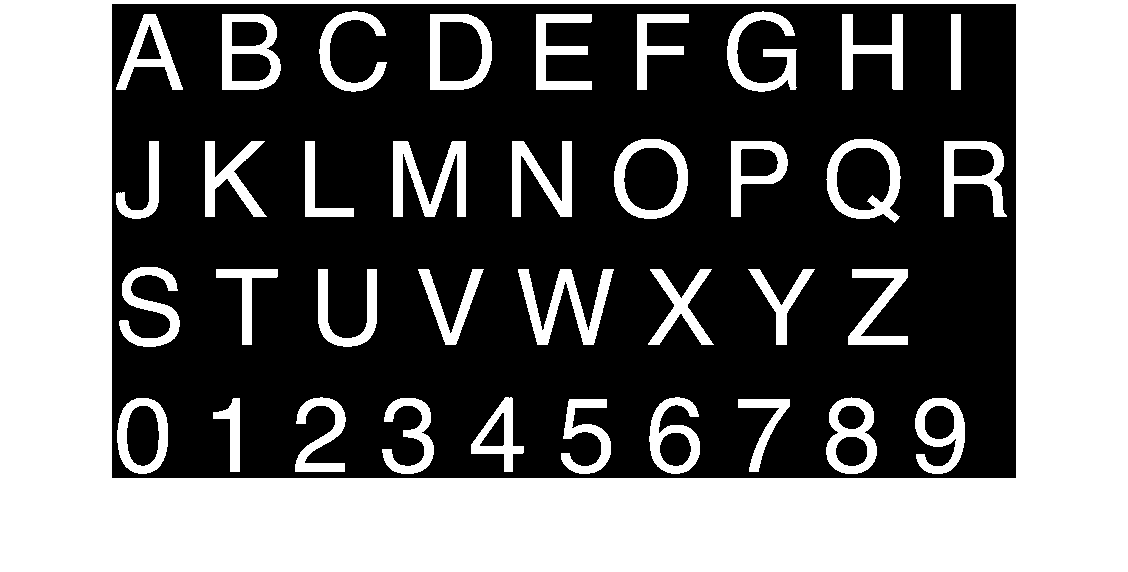

clear all, close all,
IM = imread('AllLetters.jpg');
IM2 = rgb2gray(IM);
BN  = [IM2<100];
regprops = regionprops(BN);
imshow(BN)

Control points have been selected upfront for all Helvetica letters and digits. These control points and links connecting them can be retrieved by calling function `getcontrolpoints` below. For each letter, `controlpoints` is a $2\times n_c$ matrix, with $n_c$ the number of control points, and with `controlpoints(:,i) `the pixel coordinates of control point `i`. Henceforth the column position of such a control point in `controlpoints `will be used to refer to the corresponding control point. Also for each letter, `links` is a $2\times n_L$ matrix, with $n_L$ the number of links such that a link between two control points is specified by their indices in `links(1,j) and links(2,j). ` With some basic image processing one can see the results (click R`un Section`) of connecting the control points through these links, showing that the letters and digits approximate well the original ones.

num = length(regprops);
Ibox = [regprops.BoundingBox];
Ibox = reshape(Ibox,[4 num]);

letters = ['A','B','C','D','E','F','G','H','I','J','K','L','M','N','O','P','Q','R','S','T','U','V','W','X','Y','Z','0','1','2','3','4','5','6','7','8','9'];
centroids = cat(1, regprops.Centroid);
[centroidssorted,indexsortedrow] = sort(centroids(:,2));
line1        = indexsortedrow(1:9);
[~,indexsortedcolumn1] = sort(centroids(line1,1));
line2        = indexsortedrow(10:18); [~,indexsortedcolumn2] = sort(centroids(line2,1));
line3        = indexsortedrow(19:26); [~,indexsortedcolumn3] = sort(centroids(line3,1));
line4        = indexsortedrow(27:36); [~,indexsortedcolumn4] = sort(centroids(line4,1));
orderedline1 = line1(indexsortedcolumn1);
orderedline2 = line2(indexsortedcolumn2);
orderedline3 = line3(indexsortedcolumn3);
orderedline4 = line4(indexsortedcolumn4);
orderedletters = [orderedline1; orderedline2; orderedline3; orderedline4];

BNP = zeros(size(BN));
imshow(BNP)
hold on
r = 8;
for j = 1:length(letters)
    i = orderedletters(j);
    [controlpoints,links] = getcontrolpoints(letters(j));
    a1 = Ibox(2,i);
    a2 = Ibox(1,i);
    for k = 1:size(controlpoints,2)
        rectangle('Position',[a2+controlpoints(1,k)-r/2,a1+controlpoints(2,k)-r/2,r,r],'Curvature',[1 1],'Facecolor',[1 1 1])
    end
    for k = 1:size(links,2)
        plot( [a2+controlpoints(1,links(1,k)) a2+controlpoints(1,links(2,k))] , [a1+controlpoints(2,links(1,k)) a1+controlpoints(2,links(2,k))],'Linewidth',4,'Color',[1 1 1])
    end
end

## Assignment 1: Single letter or digit

In order to achieve the mentioned goal, it is important to compute, for each letter or digit, the optimal cost and path to travel from an arbitrary control point to a destination control point while drawing that letter or digit (passing through the links of that letter or digit while drawing).

Pretty much how a person writes, the robot is allowed to lift the pen and move without drawing and lower the pen again to resume drawing (starting at another control point). However, for lifting and lowering the pen the robot must pay a time cost, assumed to be the same and equal to `costupdown. `The velocity of the robot arm is assumed to be constant and equal when it is drawing or not. It is set to 1 for convenience so that time can be expressed in the same units as distance in pixels. Thus, when drawing, the time cost between two control points is the euclidean distance of their 2D pixel array of control points retrieved from `getcontrolpoints, `and when lifting the pen going from one control point to another and lowering the pen the cost is the euclidean distance between the two control points plus  $2\times$`costupdown`. A cost `costupdown = 10 `is then equivalent to moving 10 pixels.

It is debatable if the robot should be allowed or not to write more than once on the same link connecting two control points. Here it is assumed that the robot can draw more than once the same link.

The assignment consists of providing a function `costToDestinationletter` that based on the needed input parameters provides:

i)  a vector `costM` with length corresponding to that of the number of control points of a letters and with the optimal time cost in `costM(i)` of moving in the setting described above from each control point $i$ to a selected destination given as input parameter.

ii) a cell array `path` where the length of path{i}, denoted by $L$ is the number of control points traveled along one arbitrary optimal path from control point i to the destination (there might be more than one optimal path so the length might vary). Each path{i}{j} where $j \in \{1,\dots,L\}$ contains two components

path{i}{j}{1} -> the index of control point $j$ along the optimal path

path{i}{j}{2} -> $[\matrix{b_1 & \dots&  b_{nl}}]$ , where `nl` is the number of links`,` a binary vector ( $b_\ell \in \{0,1\}$) summarizing the links which have been visited up to the present control point $j$, i.e., $b_\ell = 1$ is that link has been visited $b_\ell=0$ otherwise. The links are labeled according to their order in the matrix retrieved by `getcontrolpoints.`

The inputs are `ctrpoints`,`links `in the format retrieved by `getcontrolpoints `for a given letter`, costupdown`, the index of the destination control point `indDestination.`

As example is given next, where the desired solution is also given.

costupdown      = 10; % cost of lifting the pen and of lowering the pen as well
indDestination  = 1;  % for letter 'A' can be any number between 1 and 6 is allowed since 'A' has 6 control points
[ctrpoints,links] = getcontrolpoints('A');
% [costM,path] = costToDestinationletter(ctrpoints,links,costupdown,indDestination);


% the output when calling this function for letter A is
costM = [252.2954  224.4387  271.8728  279.8728  262.4387  234.5819];
% path is a cell array with 6 component
path{1}{1} = {[1],[0 0 0 0 0 0]};
path{1}{2} = {[2],[1 0 0 0 0 0]};
path{1}{3} = {[3],[1 1 0 0 0 0]};
path{1}{4} = {[4],[1 1 1 0 0 0]};
path{1}{5} = {[5],[1 1 1 1 0 0]};
path{1}{6} = {[6],[1 1 1 1 0 1]};
path{1}{7} = {[5],[1 1 1 1 0 1]};
path{1}{8} = {[2],[1 1 1 1 1 1]};
path{1}{9} = {[1],[1 1 1 1 1 1]};


## Assignment 2: Sequence of letters or digits

Based on assignment 1 we can summarize the cost of all the letters from all destination points to all destination points with a matrix per letter $j$ `costAllLetters{j} =` $A_{i\ell}$. The entries of this matrix are the optimal costs to move from a given initial control point indexed by $i$ to a destination control point indexed by $\ell$ as computed by `costToDestinationletter. Allcontrolpoints{j} `summarizes the control points for letter $j$ as retrieved `by getcontrolpoints`. 

Running the following code (with `flag = 1`) these matrices can be computed; f`lag = 0` will use some precomputed values for letters A, B, C.

flag = 0;
letters = ['A','B','C','D','E','F','G','H','I','J','K','L','M','N','O','P','Q','R','S','T','U','V','W','X','Y','Z','0','1','2','3','4','5','6','7','8','9'];
if(flag == 1)
    for j = 1:length(letters)
        [Allcontrolpoints{j},links] = getcontrolpoints(letters(j));
        for i = 1:size(Allcontrolpoints{j},2)
            [costI,path_{i}] = costToDestinationletter(Allcontrolpoints{j},links,costupdown,i);
            costAllLetters{j}(:,i) = costI';
        end
        pathAllLetters{j}     = path_;
    end
else
    load costAllLetters.mat
    [Allcontrolpoints{1},~]  = getcontrolpoints(letters(1));
    [Allcontrolpoints{2},~]  = getcontrolpoints(letters(2));
    [Allcontrolpoints{3},~]  = getcontrolpoints(letters(3));
end


A message/sequence of letters/digits is a string `message` containing a sequence of letters possibly with spacing characters e.g, 'AB CA', that starts and ends with a letter or digit (not a space ' '). Given a message, the information just mentioned is used to reference all the letters in a single frame using function `transformctrpoints `that also takes care of introducing spacing between the letters. This function returns a cell vector with $n$ entries, where $n$ is the number of letters/digits in the input parameter `message` different from space ' ' such that `ctrpointsglobalframe{i} `are the control points now expressed in the global frame corresponding to letter/digit in position $i$of `message`, and an auxiliary vector of indices which allows to compute (see code below) `costsperletter{i}` which is the member of `costAllLetters `corresponding to the letter in `message` in position i.

Assignment 2 relies on this information to compute the optimal path to move from an arbitrary point reference  [`initpos(1) initpos(2)] `referenced with respect to this global frame (where the control points of the output of `transformctrpoints are `referenced) to the first letter, draw the sequence of letters, and end in an arbitrary control points of the last letter.

The inputs are `costsperletter, ctrpointsglobalframe, costupdown, initpos`.  

The output is a vector with 2n entries where $n$ is the number of non space (' ') characters in `message,`

`optpath = [`$$a_{11}$$ $a_{12}$ $a_{21}$ $a_{22}$ $a_{31}$ $a_{32}$ $\dots$ $a_{n1}$ $a_{n2}$`] `

where $a_{j1}$ is the entry control point of letter $j$ and $a_{j2}$ is the exit control point of letter $j$ .

For example for  `message` = `'ab ca'`, `optpath = [5 6 12 6 1 12 2 1]` means that the robot pen will start at control point 5 of letter a, draw letter 'a' and finish in control point 6 of letter 'a'. Then move to control point '12' of letter 'B', draw letter 'B' and end in control point 6 of letter 'B'. Then move to control point 1 of letter 'C', draw letter 'C' and end in control point '12' of letter 'C'. Finally it will move to control point '2' of letter 'A', draw 'letter 'A' and end at control point 1 of letter 'A'. Each time the robot moves from one letter to another it takes a time equal to 2 `costupdown `plus the euclidean distance between the corrresponding control points in the two letters. 

% 1
message = 'AB CA';
spacing = 10;
initpos = [0 0]';
[ctrpointsglobalframe,doublemessage] = transformctrpoints(message,Allcontrolpoints,orderedletters,letters,Ibox,spacing);

figure,
for i = 1:length(ctrpointsglobalframe)
    plot(ctrpointsglobalframe{i}(1,:),max(ctrpointsglobalframe{i}(2,:))-ctrpointsglobalframe{i}(2,:),'o')
    hold on
end
axis equal

for i = 1:length(doublemessage)
    costsperletter{i} = costAllLetters{doublemessage(i)};
end
% [optpath] = optimalwritingpath(costsperletter, ctrpointsglobalframe, costupdown, initpos)
optpath = [5 6 12 6 1 12 2 1]

## Appendix

This function allows to retrieve the controlpoints and links based on the letters

function [controlpoints,links] = getcontrolpoints(letter)
switch letter
    case 'A'
        controlpoints = [6   16   31   39   54   64;
            77  51    6    6   51   77];
        links = [1 2 3 4 5 5
            2 3 4 5 2 6];
    case 'B'
        controlpoints = [7   40   48   52   48   40  48  55  48  40   7   7;
            5    5    9   20   30   37  41  54  67  72  72  37];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 12;
            2 3 4 5 6 7 8 9 10 11 12  6  1];
    case 'C'
        controlpoints = [64    60    50    27    14     9     9    14    27    50    59    65;
            26    15     8     8    16    26    56    68    76    76    68    52];
        links = [1 2 3 4 5 6 7 8 9  10 11;
            2 3 4 5 6 7 8 9 10 11 12];
    case 'D'
        controlpoints =  [7    38    51    58    58    51    38     7;
            6     6    12    25    46    63    73    73];
        links = [1 2 3 4 5 6 7 8;
            2 3 4 5 6 7 8 1];
    case 'E'
        controlpoints = [56     6     6    53     6    56;
            6     6    38    38    73    73];
        links = [1 2 3 3 5;
            2 3 4 5 6];
    case 'F'
        controlpoints =  [52     6     6    47     6 ;
            6     6    38    38    76];
        links = [1 2 3 3;
            2 3 4 5];
    case 'G'
        controlpoints =  [65    60    47    30    15     9     9    15    30    48    62    66    66    38    67;
            26    15     7     7    16    27    53    68    78    78    67    52    44    44    80];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13 12;
            2 3 4 5 6 7 8 9 10 11 12 13 14 15];
    case 'H'
        controlpoints =  [7     7     7    57    57    57;
            3    37    77    37     3    77];
        links = [1 2 2 4 4;
            2 3 4 5 6];
    case 'I'
        controlpoints =  [6     6     6;
            3    37    77];
        links = [1 2;
            2 3];
    case 'J'
        controlpoints = [40    40    36    28    17    10     6     6;
            1    63    71    76    76    71    63    53];
        links = [1 2 3 4 5 6 7
            2 3 4 5 6 7 8];
    case 'K'
        controlpoints = [6     6     6    24    54    56;
            2    47    77    31     2    77];
        links = [1 2 2 4 4
            2 3 4 5 6];
    case 'L'
        controlpoints = [6     6    50;
            1    73    73];
        links = [1 2;
            2 3];
    case 'M'
        controlpoints = [7     8    15    39    65    71    71;
            77     7     7    75     7     7    77 ];
        links = [1 2 3 4 5 6
            2 3 4 5 6 7];
    case 'N'
        controlpoints = [7     7    57    57 ;
            77     1    77     1];
        links = [1 2 3;
            2 3 4];
    case 'O'
        controlpoints = [48    63    70    70    63    48    30    14     7     7    14    30;
            6    16    32    50    66    76    76    67    50    32    16     6];
        links = [1 2 3 4 5 6 7 8 9  10 11 12;
            2 3 4 5 6 7 8 9 10 11 12 1];
    case 'P'
        controlpoints = [ 7     7     7    43    49    53    53    50    43;
            77    41     6     6    11    19    27    33    41];
        links = [1 2 3 4 5 6 7 8 9;
            2 3 4 5 6 7 8 9 2];
    case 'Q'
        controlpoints = [48    63    70    70    59    48    30    14     7     7    14    30  45 72;
            6    16    32    50    72    76    76    67    50    32    16     6  61 82];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 5 5;
            2 3 4 5 6 7 8 9 10 11 12 1 13 14];
    case 'R'
        controlpoints = [7     7     7    43    50    56    56    51    44    54    56    58;
            77    41     5     5     9    17    26    34    41    50    70    77];
        links = [1 2 3 4 5 6 7 8 9  10 11 2;
            2 3 4 5 6 7 8 9 10 11 12 9];
    case 'S'
        controlpoints = [56    51    41    22     9    10    18    52    57    57    50    41    23    12     7;
            25    13     6     6    17    30    37    47    53    67    74    77    77    71    55];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13 14;
            2 3 4 5 6 7 8 9 10 11 12 13 14 15];
    case 'T'
        controlpoints = [2    33    63    33;
            6     6     6    77];
        links = [1 2 2;
            2 3 4];
    case 'U'
        controlpoints = [6     6    11    24    38    50    56    56;
            1    55    68    75    75    68    55     2];
        links = [1 2 3 4 5 6 7;
            2 3 4 5 6 7 8];
    case 'V'
        controlpoints = [7    34    62;
            2    76     2];
        links = [1 2;
            2 3];
    case 'W'
        controlpoints = [7    26    49    72    92;
            3    76     3    76     3];
        links = [1 2 3 4;
            2 3 4 5];
    case 'X'
        controlpoints = [10    35     7    61    60;
            1    39    77    77     2];
        links = [1 2 2 2;
            2 3 4 5];
    case 'Y'
        controlpoints = [8    35    63    35;
            2    47     2    77];
        links = [1 2 2;
            2 3 4];
    case 'Z'
        controlpoints = [6    59     3    61;
            5     5    73    73];
        links = [1 2 3;
            2 3 4];
    case '0'
        controlpoints = [34    44    48    48    44    35    22    11     7     7    12    22;
            6    14    27    51    64    73    73    64    51    27    14     6];
        links = [1 2 3 4 5 6 7 8 9  10 11 12;
            2 3 4 5 6 7 8 9 10 11 12 1];
    case '1'
        controlpoints = [   2    13    21    26    26;
            19    18    13     2    75];
        links = [1 2 3 4;
            2 3 4 5];
    case '2'
        controlpoints = [   7    10    22    36    46    46    41    19    10     7    51;
            28    15     7     7   14    30    39    52    60    73    73];
        links = [1 2 3 4 5 6 7 8 9  10;
            2 3 4 5 6 7 8 9 10 11];
    case '3'
        controlpoints = [   8    10    20    36    45    45    39    23    39    48    48    42    36    21    10     7   ;
            25    13     5     5    12    27    33    37    40    44    59    68    73    73    68    60  ];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13 14 15;
            2 3 4 5 6 7 8 9 10 11 12 13 14 15 16];
    case '4'
        controlpoints = [   2    39    39    39    54;
            55     6    55    76    55  ];
        links = [1 2 3 3 3;
            2 3 4 5 1];
    case '5'
        controlpoints = [  48    12     8    15    23    33    39    47    47    42    34    20    10     6;
            6     6    41    35    32    32    35    44    57    66    73    73    67    55];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13;
            2 3 4 5 6 7 8 9 10 11 12 13 14];
    case '6'
        controlpoints = [47    44    36    24    14     9     9    13    22    34    44    48    48    43    36    24    11;
            22    12     7     7    13    23    58    68    74    74    68    58    47    38    34    34    44];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13 14 15 16 17;
            2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 7];
    case '7'
        controlpoints = [1    53    40    31    23    17 ;
            6     6    18    34    51    75 ];
        links = [1 2 3 4 5;
            2 3 4 5 6];
    case '8'
        controlpoints = [37    45    45    37    47    47    36    20     8     8    22    11    11    21;
            8    16    28    37    50    63    75    75    63    50    37    28    16     8];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13 14 4;
            2 3 4 5 6 7 8 9 10 11 12 13 14  1 11];
    case '9'
        controlpoints = [37    30    21    15     7     7    15    22    31    38    46    46    43    32    19     9     7;
            43    46    46    44    34    20     9     6     6     8    20    50    62    74    74    68    58];
        links = [1 2 3 4 5 6 7 8 9  10 11 12 13 14 15 16 1;
            2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 11];
end
end



This functrion transforms control points into a global frame

function [ctrpointsglobalframe,doublemessage] = transformctrpoints(message_,Allcontrolpoints,orderedletters,letters,Ibox,spacing)

% remove spaces
ell = 1;
auxvec = 1:length(letters);
for i = 1:length(message_)
    if message_(i) == ' '
        specialspacing(ell-1) = 1;
    else
        message(ell) = message_(i);
        d = double(message(ell));
        if d <= 57
            doublemessage(ell) = d-48 + 26 + 1;
        else
            doublemessage(ell) = d-65+1;
        end
        specialspacing(ell) = 0;
        indvector(ell) = auxvec(message(ell) == letters);
        ell = ell+1;
    end
end

%
for j = 1:length(message)
    i = orderedletters(indvector(j));
    Boundbox(:,j) = Ibox(:,i);
end


% compute dimensions of final image: sum of witdhs of bounding boxes + spacing
currentcollum = 0;
for j = 1:length(message)
    if specialspacing(j) == 0
        spacing_ = spacing;
    else
        spacing_ = 3*spacing;
    end
    ctrpoints = Allcontrolpoints{doublemessage(j)};
    for n = 1:size(ctrpoints,2)
        ctrpointsglobalframe{j}(1,n) = currentcollum + ctrpoints(1,n);
        ctrpointsglobalframe{j}(2,n) = ctrpoints(2,n);
    end
    currentcollum = currentcollum+Boundbox(3,j)+spacing_;
end
end